# **InverseJacobiNC**

[Inverse of the Jacobi elliptic function nc](https://dlmf.nist.gov/22.15)

## Definition


$${\textrm{nc}}^{-1} \left(x\left|m\right.\right)\equiv \left\lbrace \begin{array}{cc}
\mathit{\mathbf{F}}\left(\sqrt{1-x^{-2} }\left|m\right.\right) & -\infty <m\le 1\\
\frac{{\textrm{nd}}^{-1} \left(x\left|m^{-1} \right.\right)}{\sqrt{m}} & 1<m<\infty 
\end{array}\right.$$



$${\mathrm{nc}}^{-1} \left(x,k\right)\equiv {\mathrm{nc}}^{-1} \left(x\left|k^2 \right.\right)$$


where *m *is the parameter, *k *is the modulus, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ is  the Jacobi  form of the elliptic integral of the first kind.

Domain: If $-\infty <m\le 1$ (or $|k|\le 1$) then $|x|\ge 1$. If $m>1$ (or $k>1$)  then  $1<x<1/\sqrt{1-m^{-1} }$. For the specified domain, the  codomain  is the set of real numbers.

Basic features:

Special values:

${\mathrm{nc}}^{-1} \left(-\infty \left|m\right.\right)=K\left(m\right)$,   ${\textrm{nc}}^{-1} \left(-1\left|m\right.\right)=2K\left(m\right)$,    ${\mathrm{nc}}^{-1} \left(1\left|m\right.\right)=0$,    ${\textrm{nc}}^{-1} \left(\infty \left|m\right.\right)=K\left(m\right)$

${\mathrm{nc}}^{-1} \left(x\left|0\right.\right)={\mathrm{sec}}^{-1} x$,   ${\mathrm{nc}}^{-1} \left(x\left|1\right.\right)={\mathrm{cos}\textrm{h}}^{-1} \left(x\right)$

Identities:


$${\mathrm{nc}}^{-1} \left(\mathrm{nc}\left(x\left|m\right.\right)\left|m\right.\right)=x,\;\;\;\;\left|x\right|<K\left(m\right)$$



$$\textrm{nd}\;\left({\textrm{nd}}^{-1} \left(x\left|m\right.\right)\right)=x$$


$K\left(m\right)$ is the complete elliptic integral of the first kind .

## Syntax

Y = InverseJacobiNC(X,K)

y = ijnc(x,k)

Y = mInverseJacobiNC(X,M)

y = mijnc(x,m)

**Note. **InverseJacobiNC is equal to the function EllipticF

## Description

**Y = InverseJacobiNC(X,K)** return the Jacobi form of elliptic integral of the first kind ${\mathrm{nc}}^{-1} \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **InverseJacobiNC** is the wrapper function which calls the functionc **ijnc** element-wise via the function **ufun2**.

**y = ijnc(x,k)** return the value of the Jacobi form of elliptic integral of the first kind  ${\mathrm{nc}}^{-1} \left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. ijnc is the wrapper function which calls the functionc **mijnc**.

**Y = mInverseJacobiNC(X,M)** returnc the Jacobi form of elliptic integral of the first kind ${\mathrm{nc}}^{-1} \left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mInverseJacobiNC** is the wrapper function which calls the functionc mijnc element-wise via the function **ufun2**.

**y = mijnc(x,m)** compute value of the Jacobi form of elliptic integral of the first kind  ${\mathrm{nc}}^{-1} \left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mijnc **call the function **melF **for calculation of ${\mathrm{nc}}^{-1} \left(x\left|m\right.\right)$.

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 1.5;
[ijnc(x,k), InverseJacobiNC(x,k), mijnc(x,k^2), mInverseJacobiNC(x,k^2)]

ans =    0.864118685103278   0.864118685103278   0.864118685103278   0.864118685103278


% Maple 0.864118685103277_917

Accuracy.

fprintf('%.16g\n',mijnc(1.5,-4)) 

0.6578468439116356


%  Maple 0.6578468439116355_75

Special values

m = -2;
x = 1.5;  % |x| <= 1
mijnc(0,m)

ans = NaN

disp(mijnc(1,m) - 0)  % m < 1 !!!

     0



mijnc(x,-inf)

ans = NaN

disp(mijnc(x,0) - asec(x)) 

    -1.110223024625157e-16



disp(mijnc(x,1) - acosh(x))

     0



mijnc(inf,m)  % x = 0

ans = 1.1714

Identities

m = -2;
x = 1.5; % |x| <= 1
disp(mJacobiNC(mInverseJacobiNC(x,m),m)-x)

    -4.440892098500626e-16




k = 0.99995;
x = 0.9999*elK(k);
disp(InverseJacobiNC(JacobiNC(x,k),k)-x)

     3.389999392311438e-11



m = 2; % m>1
x = 1.2; % x > sqrt(m)
disp(mijnc(x,m)-mijnd(x,1/m)/sqrt(m))

     0



**Vector input**

k = [0.1, 0.5, 0.89, 0.99995];
x = 1.2*ones(size(k));
disp(InverseJacobiNC(x,k)-InverseJacobiND(x,1./k)./k)

   1.0e-15 *

                   0                   0   0.111022302462516   0.111022302462516



**Matrix input**

k = [0.1, 0.5, 0.89; 2, 3, 0.99995 ];
x = 1.02; %*ones(size(k));
disp(InverseJacobiNC(x,k)-InverseJacobiND(x,1./k)./k)

   1.0e-16 *

   0.277555756156289                   0                   0
                   0                   0                   0



## **Plot **

**Example 1**

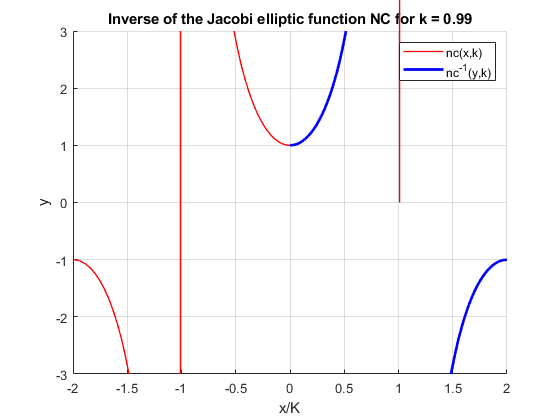

figure
hold on
x=-2:0.01:2;
k = 0.99;
K = elK(k);
plot(x,JacobiNC(K*x,k),'LineWidth',1.0,'Color','red')
x=-12:0.01:12;
plot(InverseJacobiNC(x,k)/K,x,'LineWidth',2,'Color','blue')
legend('nc(x,k)','nc^{-1}(y,k)') %,'Position','best')
xlabel('x/K')
ylabel('y')
%xlim([-1.1 1.1])
ylim([-3 3])
title(sprintf('Inverse of the Jacobi elliptic function NC for k = %g',k))
grid on
hold off

**Example 2**

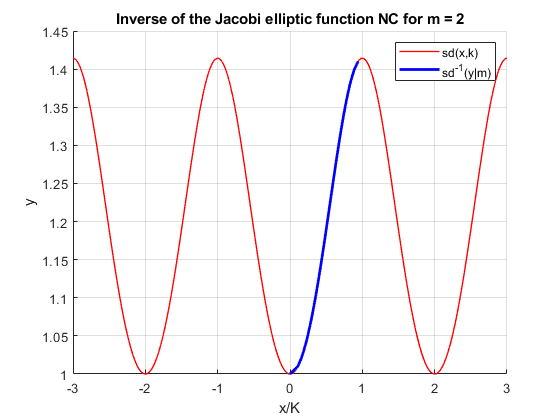

figure
hold on
x=-3:0.01:3;
m = 2;
if m < 1
    M = melK(m);
    xlabel('x/K')
    ylim([-5 5])
elseif m > 1
    M = melK(1/m)/sqrt(m);
    xlabel('x/K')
else
    M = 1;
    xlabel('x')
end
plot(x,mJacobiNC(M*x,m),'LineWidth',1.0,'Color','red')
x=-102:0.01:102;
plot(mInverseJacobiNC(x,m)/M,x,'LineWidth',2,'Color','blue')
legend('sd(x,k)','sd^{-1}(y|m)') %,'Position','best')
ylabel('y')
%xlim([-1.1 1.1])
title(sprintf('Inverse of the Jacobi elliptic function NC for m = %g',m))
grid on
hold off

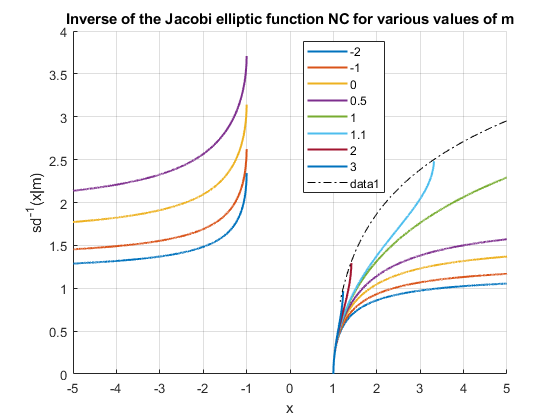

figure
hold on
X = -5:0.001:5;
M = [-2,-1,0,0.5,1,1.1,2,3];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mInverseJacobiNC(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) 0 4])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Inverse of the Jacobi elliptic function NC for various values of m')
N=1:0.01:4;
X = 1./sqrt(1-1./N);
plot(X,mInverseJacobiNC(X,N),'k-.')
%plot(-X,-mInverseJacobiNC(X,N),'k-.')
xlabel('x')
ylabel('sd^{-1}(x|m)')

**Example 4**

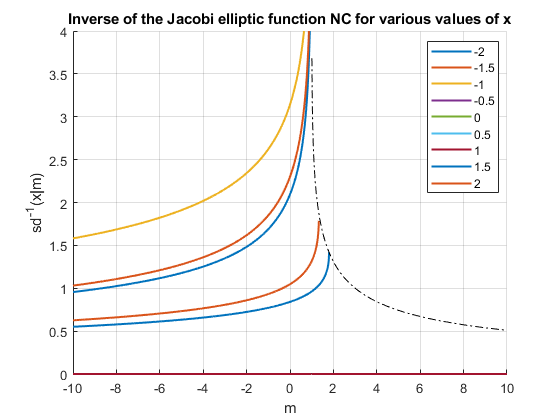

figure
hold on
M = -10:0.01:10;
X = [-2,-1.5,-1,-0.5,0,0.5,1,1.5,2];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mInverseJacobiNC(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -3 3])
ylim([0 4])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Inverse of the Jacobi elliptic function NC for various values of x')
xlabel('m')
ylabel('sd^{-1}(x|m)')
M = 1:0.01:10;
F = mInverseJacobiNC(1./sqrt(1-1./M),M);
plot(M,F,'k-.')
%plot(M,-F,'k-.')
hold off

**Example 5**

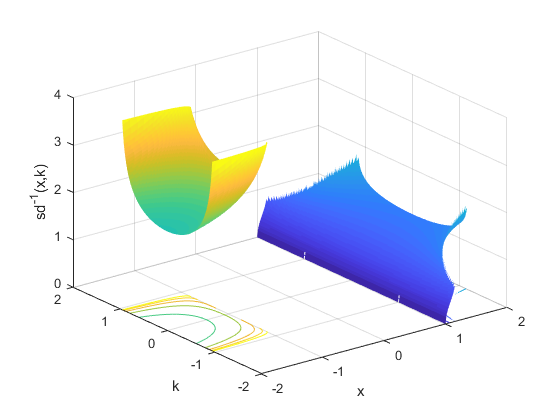

figure
x=-2:0.01:2;
k=-2:0.01:2;
zz = 4;
[X,M]=meshgrid(x,k);
hs=surfc(X,M,InverseJacobiNC(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:zz/10:zz;
view(3)
caxis([0 zz])
xlabel('x')
ylabel('k')
zlabel('sd^{-1}(x,k)')
zlim([0 zz])
grid on

**Example 6**

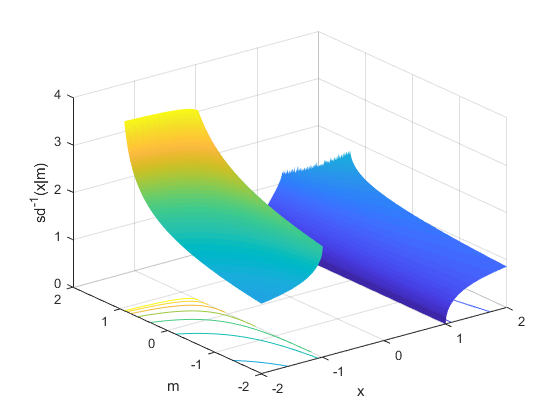

figure
x=-2:0.01:2;
m=-2:0.01:2;
zz = 4;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mInverseJacobiNC(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:zz/10:zz;
view(3)
caxis([0 zz])
xlabel('x')
ylabel('m')
zlabel('sd^{-1}(x|m)')
zlim([0 zz])
grid on

**Example 7**

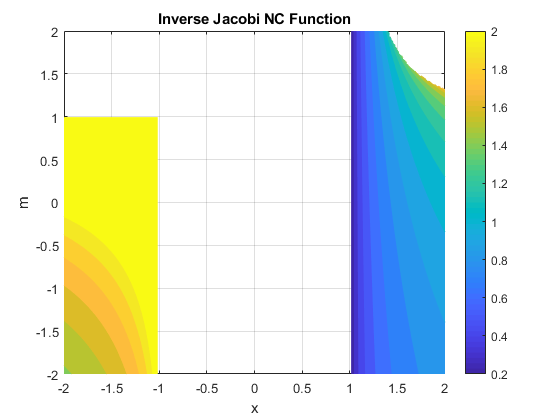

figure
f = @(x,m)mInverseJacobiNC(x,m);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-2:0.1:2,'MeshDensity',200)
title('Inverse Jacobi NC Function')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 8**

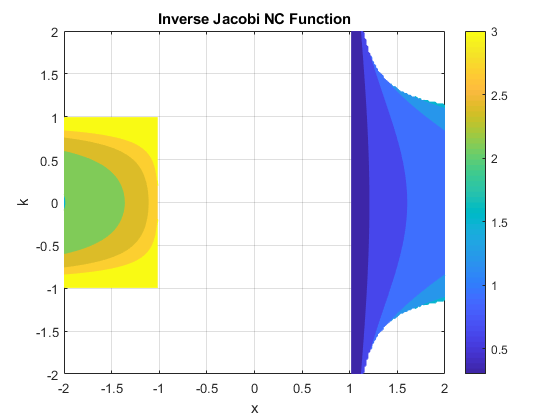

figure
f = @(x,k)InverseJacobiNC(x,k);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Inverse Jacobi NC Function')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functionc](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functionc, NIST Digital Library of Mathematical Functionc](https://dlmf.nist.gov/22)

[Jacobi elliptic functionc, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also